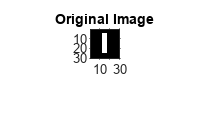


% Spectrum of an image
% Create an image with a white rectangle and black background.
clear; close all; clc;

% Generate an image
im = zeros(30,30);
%%
im(5:24,13:17)=1;
%%
figure();
imshow(im); title('Original Image'); axis on

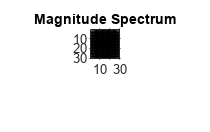

%%
% display('Spectrum of the image');
% display('Press any Key');
% pause

% Find the Spectrum using FFT
imF = fft2(im);
%%
imF_mag = abs(imF);
figure(); imshow(imF_mag,[]);title('Magnitude Spectrum'); axis on

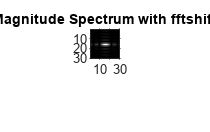

%%
% display('Spectrum of the image with fftshift');
% display('Press any Key');
% 
% pause

% The zero-frequency coefficient is displayed in the upper left hand corner.
% To display it in the center, you can use the function fftshift.
imF_mag = fftshift(imF);

imF_mag = abs(imF_mag);       
figure(); imshow(imF_mag,[]);title('Magnitude Spectrum with fftshift'); axis on

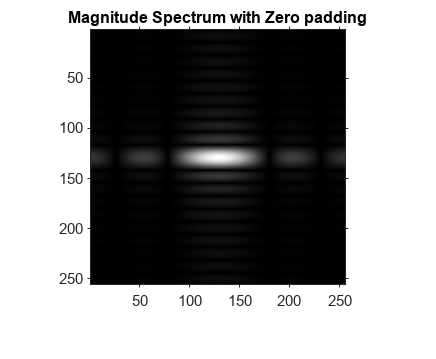

%%
% display('Spectrum of the image with zero padding');
% display('Press any Key');
% pause

% To create a finer sampling of the Fourier transform, 
% you can add zero padding to im when computing its DFT.

imF=fft2(im, 256,256);
imF_mag = abs(fftshift(imF));       
figure(); imshow(imF_mag,[]); title('Magnitude Spectrum with Zero padding'); axis on

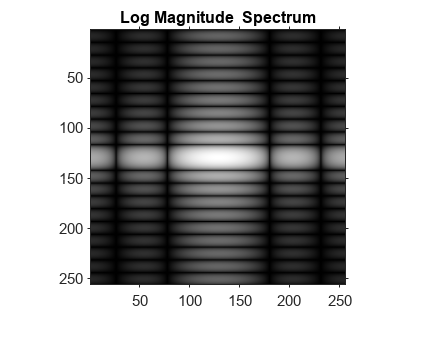

%%
% display('Spectrum of the image with log magnitude');
% display('Press any Key');
% pause

% To brighten the display, you can use a log function
imF_log_mag=log(1+imF_mag);
figure,imshow(imF_log_mag,[]);title('Log Magnitude  Spectrum'); axis on


disp('End of the program');

End of the program
